## 数据平滑

### 1 移动窗口方法

数据平滑：消除数据中不需要的噪声或行为

例如：每分钟测量一次风速，持续3小时

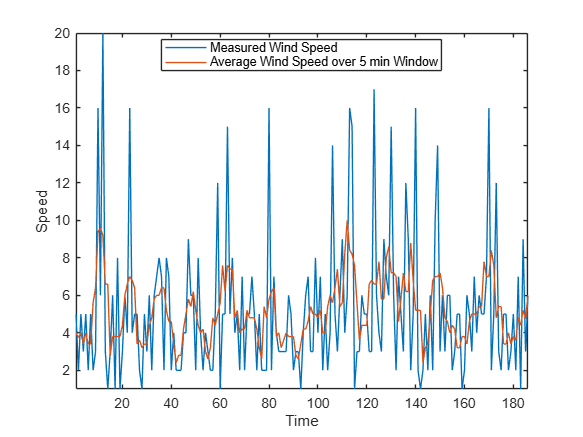

load windData.mat
mins = 1:length(speed);
window = 5;
meanspeed = movmean(speed,window);
plot(mins,speed,mins,meanspeed)
axis tight
legend('Measured Wind Speed','Average Wind Speed over 5 min Window','location','best')
xlabel('Time')
ylabel('Speed')

### 2 移动窗口方法 - 并非总是适用

2.1 考虑一个注入了随机噪声的正弦信号。

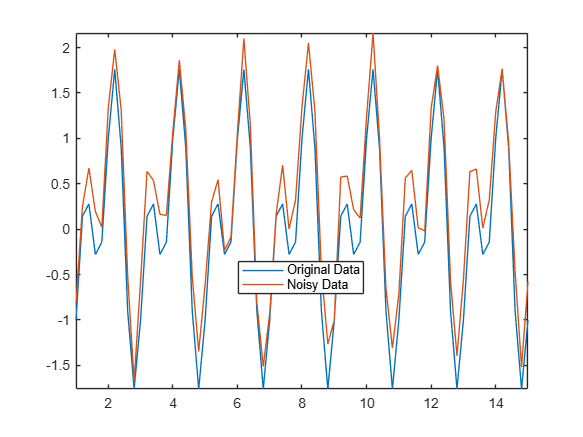

t = 1:0.2:15;
A = sin(2*pi*t) + cos(2*pi*0.5*t);
Anoise = A + 0.5*rand(1,length(t));
plot(t,A,t,Anoise)
axis tight
legend('Original Data','Noisy Data','location','best')

2.2 使用窗口大小为3的移动均值来平滑含噪声的数据。

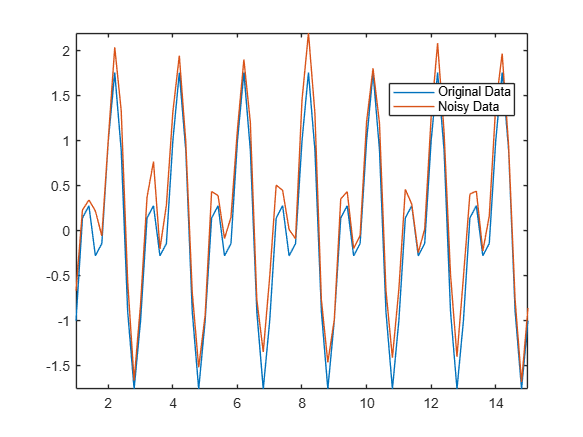

t = 1:0.2:15;
A = sin(2*pi*t) + cos(2*pi*0.5*t);
Anoise = A + 0.5*rand(1,length(t));
plot(t,A,t,Anoise)
axis tight
legend('Original Data','Noisy Data','location','best')

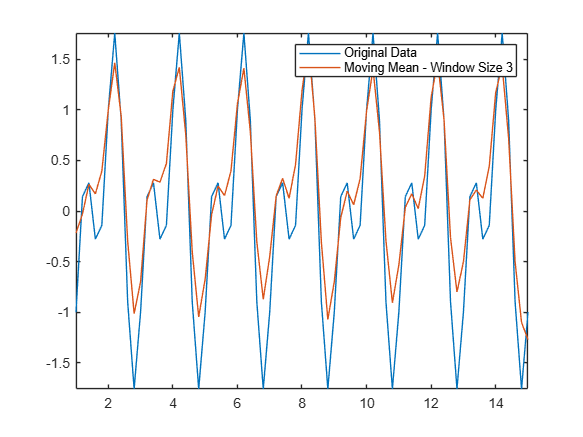

window = 3;
Amean = movmean(Anoise,window);
plot(t,A,t,Amean)
axis tight
legend('Original Data','Moving Mean - Window Size 3')

2.3 更大的窗口？数据更平滑了，但波谷点消失了。

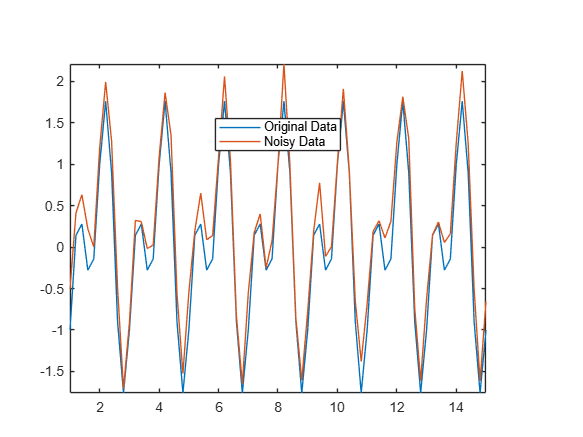

t = 1:0.2:15;
A = sin(2*pi*t) + cos(2*pi*0.5*t);
Anoise = A + 0.5*rand(1,length(t));
plot(t,A,t,Anoise)
axis tight
legend('Original Data','Noisy Data','location','best')

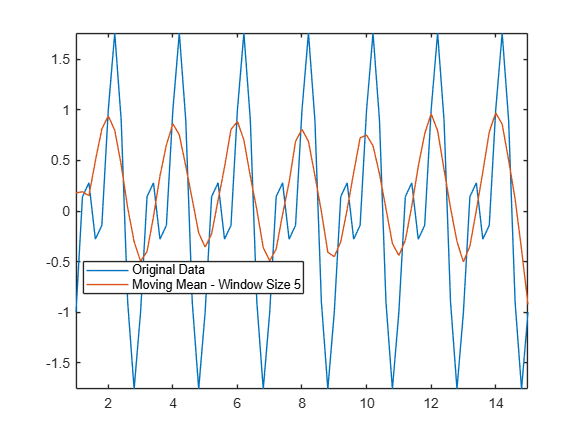


Amean = movmean(Anoise,5);
plot(t,A,t,Amean)
axis tight
legend('Original Data','Moving Mean - Window Size 5','location','best')

**作业：**研究并尝试对此数据使用不同的平滑方法。

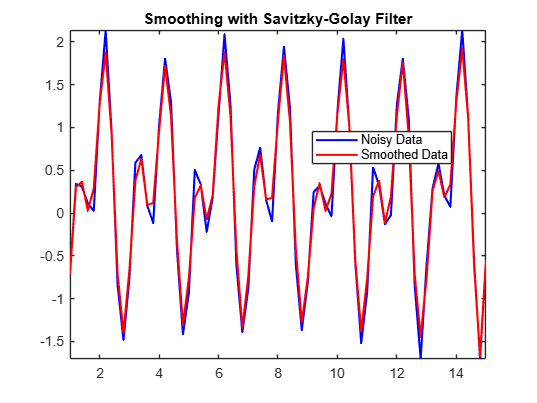

t = 1:0.2:15;
A = sin(2*pi*t) + cos(2*pi*0.5*t);
Anoise = A + 0.5*rand(1,length(t));
% Savitzky-Golay 滤波器参数
polynomial_order = 3; % 您可以调整此参数
window_size = 5;      % 必须为奇数

% 应用滤波器
smoothed_data = sgolayfilt(Anoise, polynomial_order, window_size);

% 绘制结果
figure;
plot(t, Anoise, 'b', t, smoothed_data, 'r', 'LineWidth', 1.5);
axis tight;
legend('Noisy Data', 'Smoothed Data', 'Location', 'best');
title('Smoothing with Savitzky-Golay Filter');

## 3 常用平滑方法

`smoothdata`函数提供了几种平滑选项

• 例如 Savitzky-Golay 方法，

• 默认情况下，`smoothdata`会选择一个最佳猜测的窗口大小

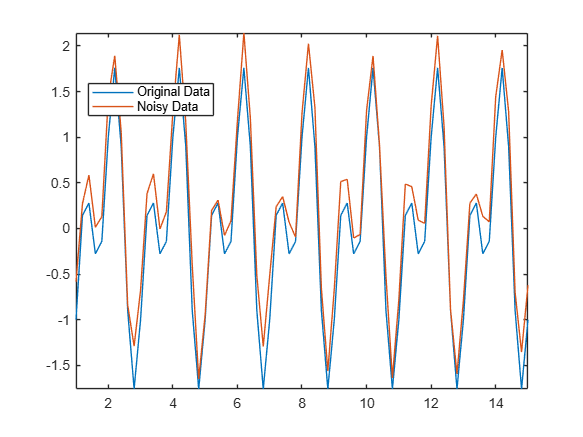

t = 1:0.2:15;
A = sin(2*pi*t) + cos(2*pi*0.5*t);
Anoise = A + 0.5*rand(1,length(t));
plot(t,A,t,Anoise)
axis tight
legend('Original Data','Noisy Data','location','best')

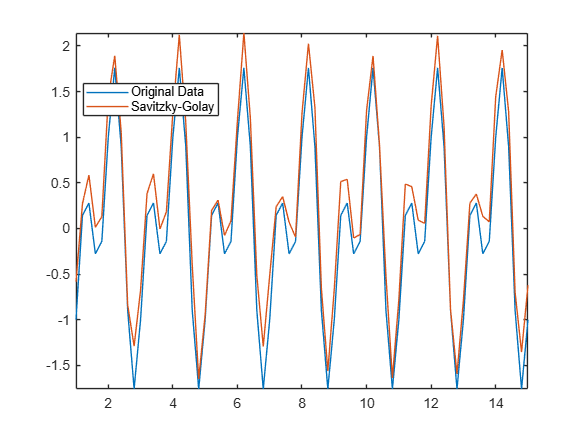

[Asgolay,window] = smoothdata(Anoise,'sgolay');
plot(t,A,t,Asgolay)
axis tight
legend('Original Data','Savitzky-Golay','location','best')